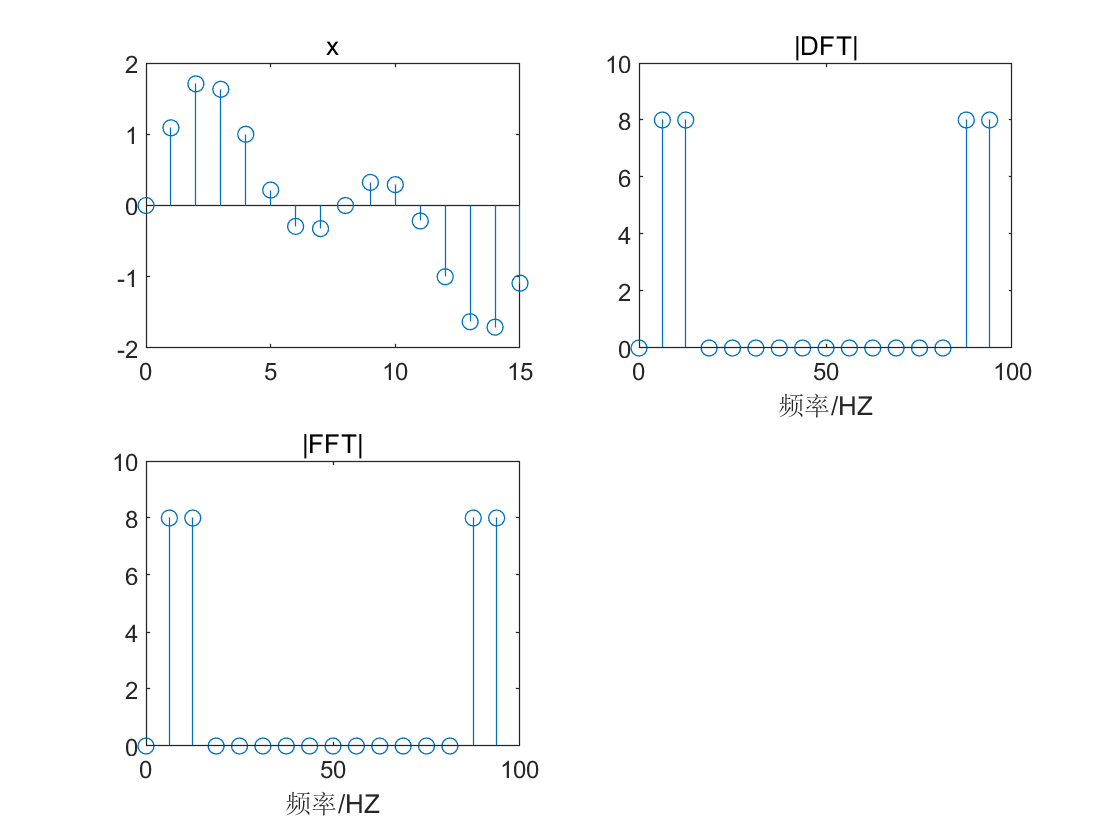

N=16;fs=100;
n=0:N-1;
f=n*fs/N;
xn=sin(n*pi/8)+sin(n*pi/4);
k=0:N-1;
WN=exp(-1i*2*pi/N);
nk=n'*k;
WNnk=WN.^nk;
Xk=xn*WNnk;
Y=abs(fft(xn));    
subplot(2,2,1),stem(n,xn);title('x');
subplot(2,2,2),stem(f,abs(Xk));title('|DFT|');xlabel('频率/HZ');
subplot(2,2,3),stem(f,Y);title('|FFT|');xlabel('频率/HZ');